clear; clc;

% test_csv = readmatrix("motor_data/test1.csv")
test_csv = readmatrix("motor_data/test_stm_kalman.csv")

test_csv = 1.0e+07 *

       NaN       NaN       NaN       NaN       NaN
         0    1.1254         0         0         0
    0.0000    1.1256         0         0         0
    0.0000    1.1258         0         0         0
    0.0000    1.1260         0         0         0
    0.0000    1.1262         0         0    0.0000
    0.0000    1.1264         0         0    0.0000
    0.0000    1.1265         0         0    0.0000
    0.0000    1.1267         0         0    0.0000
    0.0000    1.1269         0         0    0.0000


test_csv(2,2)

ans = 11254221

data_length = length(test_csv(:,2))-1

data_length = 5324

time = test_csv(2:data_length+1, 2);    % мкс
q = test_csv(2:data_length+1, 3);  % рад
w = test_csv(2:data_length+1, 4);    % рад/с
dw = test_csv(2:data_length+1, 5);  % рад/с^2

t_start = time(1);
time = (time - t_start)/1000000;    % с

ew = zeros(1, data_length);
edw = zeros(1, data_length);

dI = zeros(1, data_length);
dI_orig = zeros(1, data_length);

f_w = 1

f_w = 1

f_b = 0.7

f_b = 0.7000

f_i = 1

f_i = 1

f_di = 0.05

f_di = 0.0500


for k = 2:data_length
    dt = time(k)-time(k-1);

    ew(k) = ( q(k)-q(k-1) )/dt;
    edw(k) = ( w(k)-w(k-1) )/dt;

%     dticks(k) = dticks(k-1)*(1-f_w) + f_w * ( q(k)-q(k-1) )/dt;
%     ddticks(k) = ddticks(k-1)*(1-f_b) + f_b * ( dticks_orig(k)-dticks_orig(k-1) )/dt;
%     dI(k) = dI(k-1)*(1-f_di) + f_di * ( current(k)-current(k-1) )/dt;
end

% dticks = smooth(dticks, 3);

% current = smooth(current, 3);
% ddticks = smooth(ddticks, 12);
% dI = smooth(dI, 5);

w_smooth = smooth(w, 3);
dw_smooth = smooth(dw, 50);

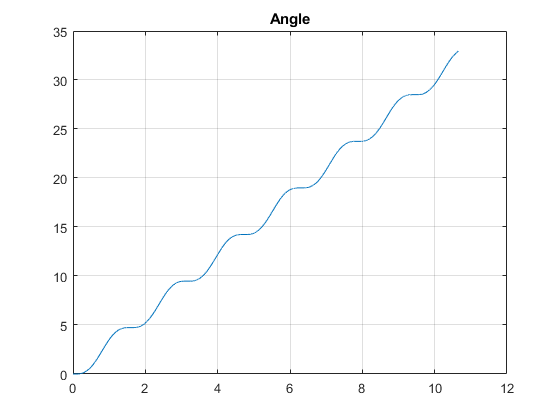

figure;
plot(time, q)
title("Angle")
xlim("auto")
ylim("auto")
grid on

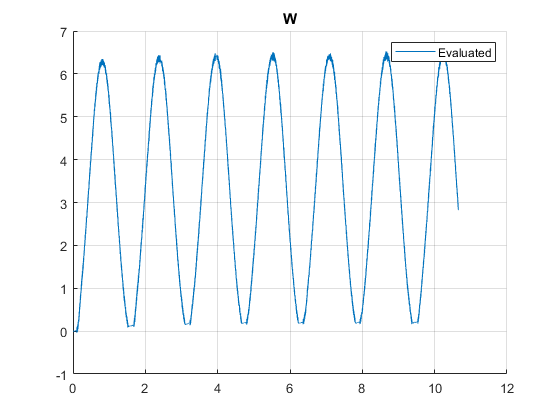


figure;
hold on
% plot(time, ew, '--')
plot(time, w)
% plot(time, w_smooth)
hold off
title("W")
xlim("auto")
ylim("auto")
grid on
legend("Evaluated", "Original", "Orig filtered")

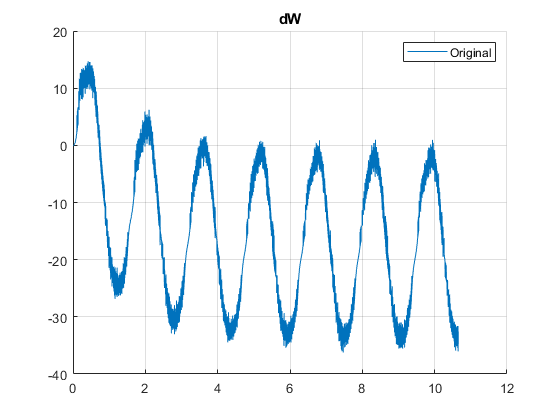


figure
hold on
plot(time, dw)
% plot(time, dw_smooth)
% plot(time, edw)
hold off
title("dW")
xlim("auto")
ylim("auto")
grid on
legend("Original", "Filtered", "Evaluated")

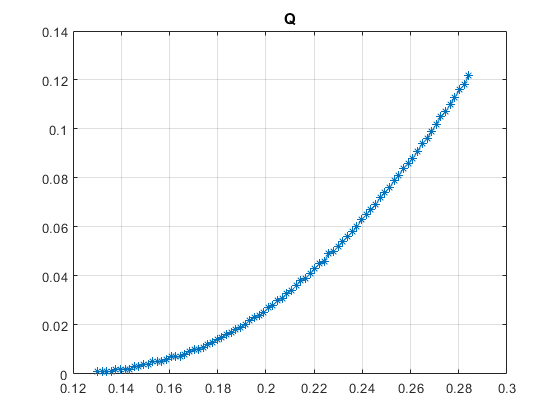


start = 70;
finish = 150;

figure;
plot(time(start:finish), q(start:finish), '*-')
title("Q")
xlim("auto")
ylim("auto")
grid on

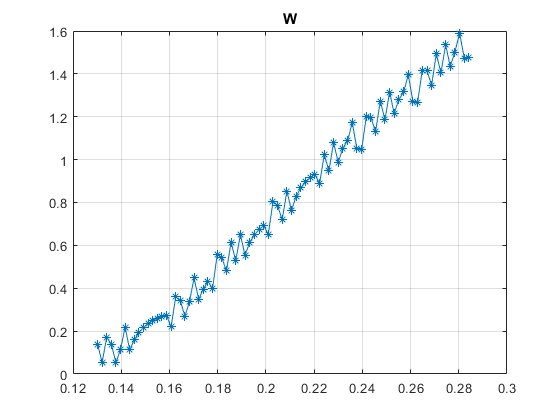


figure;
plot(time(start:finish), w(start:finish), '*-')
title("W")
xlim("auto")
ylim("auto")
grid on

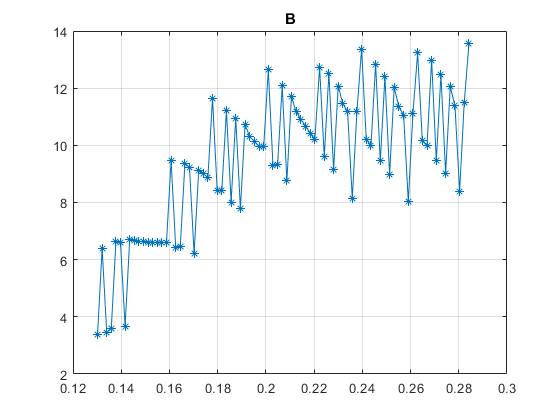


figure;
plot(time(start:finish), dw(start:finish), '*-')
title("B")
xlim("auto")
ylim("auto")
grid on


% figure;
% plot(time(start:finish), current(start:finish), '*-')
% title("I")
% xlim("auto")
% ylim("auto")
% grid on
% 
% figure;
% plot(time(start:finish), input(start:finish), '*-')
% title("U")
% xlim("auto")
% ylim("auto")
% grid on